# Computer Excersice 2

## 1.  Working with AR-, MA- and ARMA-models

### 1.1  Modelling and simulation of AR(1)-processes 

% The AR(1) process
C=1;
a1=2;
A=[1 a1];
subplot(221)
zplane(C,A)

**Q1:** Yes this matches the theory. Since $R_X(f)=\frac{\sigma^2}{|{A(f)|^2}$ for an AR(p)-process we have the poles (lite osäker här)$0=|A(f)|^2=|\sum \limits_{k=0}  \limits^^{1} a_k e^{-i2\pi fk}|^2=...=1+a_1^2+2a_1\cos{2\pi f}$.

subplot(222)
sigma=2;
[H,w]=freqz(sigma*C,A,1024,'whole');
R=abs(H).^2;
plot(w(1:513)/2/pi,R(1:513))

subplot(223)
r=ifft(R);
plot([0:39],r(1:40))

**Q2: **Behaves as expected. Changing sign inverts the spectral density, which makes sense because we go from a pole at frequency 1/2 to 0. This consequently impacts the covariance function which goes from much periodicity to none. 

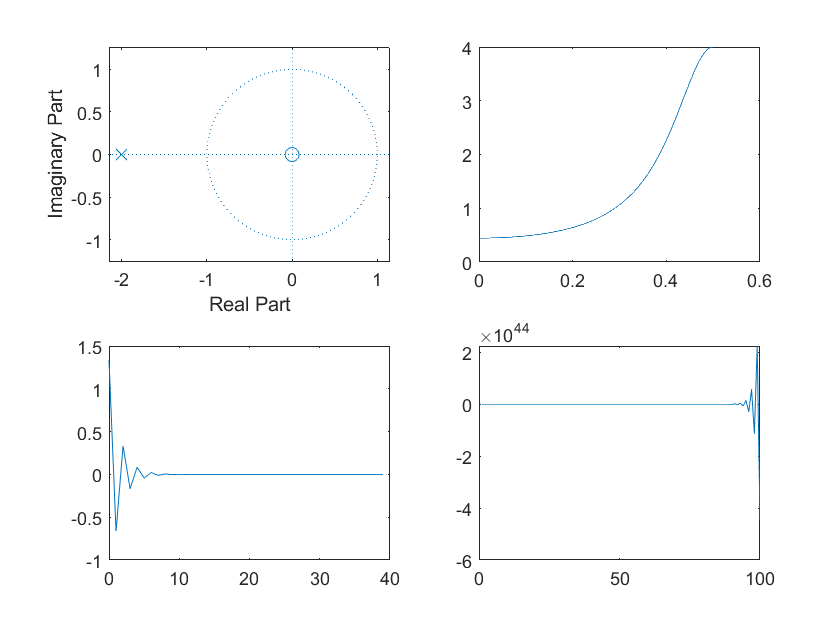

% To simulate a realisation of a Gaussian AR-process, we generate a
% sequence of independent and Gaussian distributed stochastic variables,
% with mean zero and variance σ and use this sequence as input of our model,
n=150;
sigma2=2;
e = sqrt(sigma2)*randn(n,1);
x = filter(C, A, e);
xstat=x(51:150);
subplot(224)
plot(xstat)

**Q3: **We can prove this with $|A(f)|^2_{unstable}=1+\frac{1}{a_1^2}+\frac{2}{a_1}\cos{2\pi f}=\frac{1}{a_1^2}(1+a_1^2+2a_1\cos{2\pi f})=\frac{1}{a_1^2}|A(f)|^2_{stable}$